# Git y MATLAB 

## Objetivos de aprendizaje 

- *Reconocer el vocabulario básico relacionado con el uso de Git para control de versiones*

- *Usar MATLAB para clonar, obtener (pull), enviar (push) y guardar (commit) repositorios Git*

- *Usar MATLAB para localizar, abrir y comparar diferentes versiones de un archivo en un repositorio Git.*

## Conceptos y vocabulario

Esto está pensado como un glosario de términos que probablemente encontrarás al comenzar a trabajar con Git, aunque puede que no los encuentres todos al mismo tiempo.

**Source Control**, también conocido como control de fuentes o control de versiones, es un sistema que gestiona los cambios en documentos, código y otros conjuntos de información. Un ejemplo de control de versiones es cuando puedes acceder a  versiones pasadas de un documento. Es especialmente útil en entornos colaborativos donde varias personas trabajan en el mismo proyecto. Imagina escribir un trabajo en grupo donde todos pueden trabajar en sus secciones simultáneamente. El control de versiones realiza un seguimiento de las ediciones de cada persona, permitiendo al equipo ver quién hizo cambios y cuándo. También te permite volver a versiones anteriores si es necesario, como un botón de "deshacer" avanzado. Este sistema ayuda a prevenir conflictos y la pérdida de datos, asegurando que todos trabajen con la información más actualizada. Una herramienta popular para el control de versiones es Git, que se utiliza ampliamente en el desarrollo de software, pero puede aplicarse a cualquier proyecto que involucre archivos digitales.

**Git:** Una herramienta comúnmente usada para el control de versiones.

**repositorio:** Una carpeta que contiene archivos y el historial de Git de esos archivos.

**licencia:** El acuerdo legal que establece quién puede usar el contenido en un repositorio Git y cómo se le permite utilizarlo. Este repositorio se comparte bajo una [licencia BSD-3](matlab:open('LICENSE.md')).

**remote:** Una forma abreviada de referirse a la ubicación en la nube donde estás almacenando la copia compartida de tu repositorio. En este caso, utilizarás un repositorio remoto en GitHub.

**clone:** El término de Git para crear la copia local inicial de un repositorio Git.

**pull:** La acción de actualizar tu copia local de un repositorio para que coincida con la versión almacenada en el repositorio remoto usando Git.

**commit:** La acción de crear una versión guardada de tus archivos en un repositorio Git. También se te pedirá que agregues un **mensaje de commit** donde describas los cambios que has realizado desde la versión guardada anterior.

**branch:** El término que Git utiliza para describir diferentes versiones, pero relacionadas, de tu carpeta y los archivos que contiene y que se están desarrollando en paralelo. En este caso, solo usarás la rama principal y no crearás ninguna otra rama.

**push:** La acción de usar tu repositorio local para actualizar la versión en una ubicación remota, como GitHub, usando Git.

**SHA:** Una cadena hexadecimal (alfanumérica) que identifica cada commit en Git, usualmente mostrada como los últimos siete dígitos: por ejemplo, d9ef0e5.

## Creando un repositorio Git

### En tu directorio (localmente)

Si estás trabajando en MATLAB y quieres usar Git como control de versiones, puedes convertir tu directorio actual en un repositorio Git local ejecutando el comando:

gitinit

### Desde un repositorio remoto mediante clonación

Las instrucciones paso a paso se encuentran en la documentación: [Clonar un repositorio Git](https://www.mathworks.com/help/matlab/matlab_prog/clone-git-repository.html)

Para practicar, puedes clonar el material del curso existente [Programming: Structuring Code](https://github.com/MathWorks-Teaching-Resources/Programming-Structuring-Code).

Paso 1. En la página principal de GitHub de un repositorio, debes buscar el botón verde que dice "Code". Al hacer clic en él se abrirá un menú contextual donde puedes encontrar la dirección para clonar el repositorio:

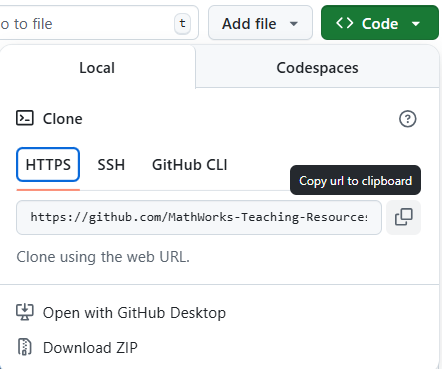

Si vas a trabajar regularmente con el sistema remoto, puede valer la pena configurar una clave SSH, pero por ahora puedes usar la dirección HTTPS para clonar este repositorio público. Usa el botón con los cuadrados superpuestos para copiar la dirección al portapapeles.

Paso 2. Ve a la pestaña HOME en la barra de herramientas de MATLAB y expande el menú desplegable New:

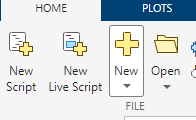

Luego selecciona Git Clone:

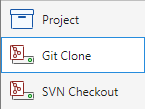

Paso 3: Pega la dirección del repositorio Git remoto en el campo URL y usa el explorador de archivos para seleccionar una nueva ubicación de carpeta vacía donde guardar tu copia del repositorio.

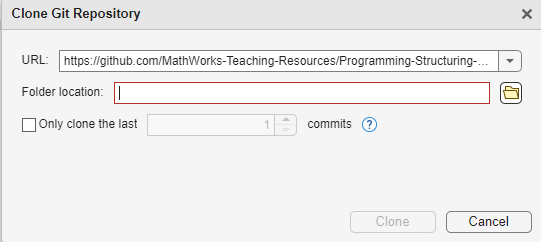

Si te preocupa el espacio, puedes seleccionar la casilla "Only clone the last 1 commits". Luego haz clic en Clone.

## Haciendo commit en un repositorio Git

El proceso de indicarle a Git que quieres guardar la versión actual para referencia futura se llama "hacer commit" y la descripción del estado actual y/o de los cambios que se han realizado desde la versión previamente guardada se llama "mensaje de commit".

Primero, asegúrate de que has definido las credenciales apropiadas en la Configuración de MATLAB bajo Source Control:

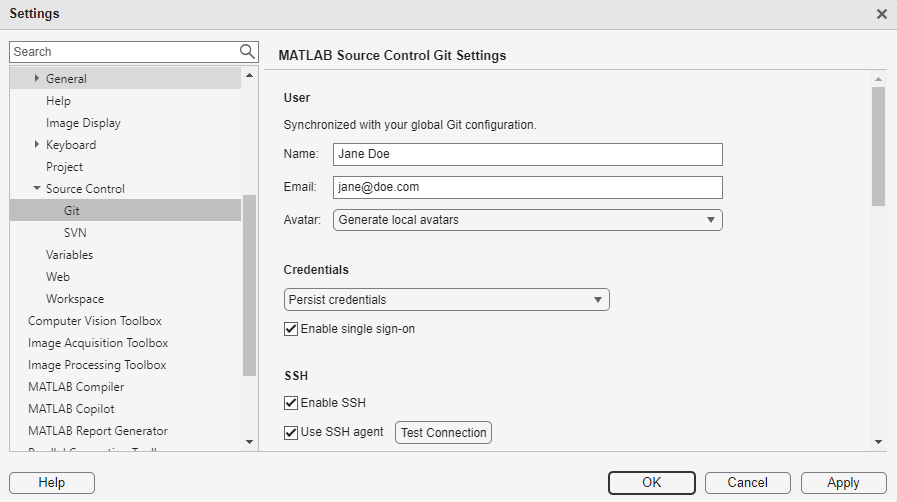

### Si estás trabajando en R2025a

Puedes usar el panel de Source Control   para identificar y hacer commit de los cambios en tus archivos.

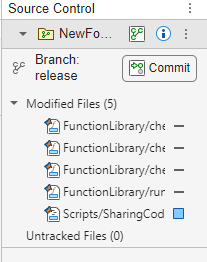

Al hacer clic en el botón Commit se abrirá un diálogo de commit como este:

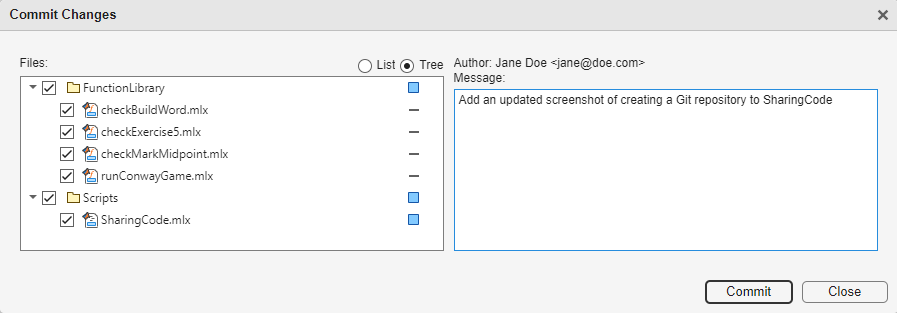

Escribe el mensaje de commit en la ventana de la derecha, aquí es "Add an updated screenshot of creating a Git repository to SharingCode", luego haz clic en Commit. No podrás hacer commit sin escribir un mensaje de commit, ya que es parte de la estructura requerida por Git.

### Si estás trabajando en R2024b

Para usar Git desde la barra de herramientas, debes formatear tu trabajo como un proyecto.

Ve a la pestaña HOME en la barra de herramientas de MATLAB y expande el menú desplegable New:

Luego selecciona Project y crea un nuevo proyecto desde tu carpeta actual:

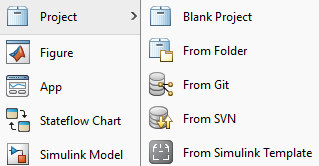

Luego, en la pestaña Project, puedes encontrar la sección Source Control,

incluyendo  Commit.

**Consejo profesional:** Si has inicializado un repositorio git, pero ves  en la pestaña Project, selecciónalo. Luego selecciona "Add Project to Source Control"

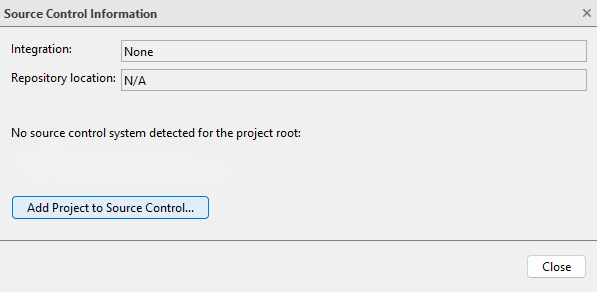

Y selecciona Convert:

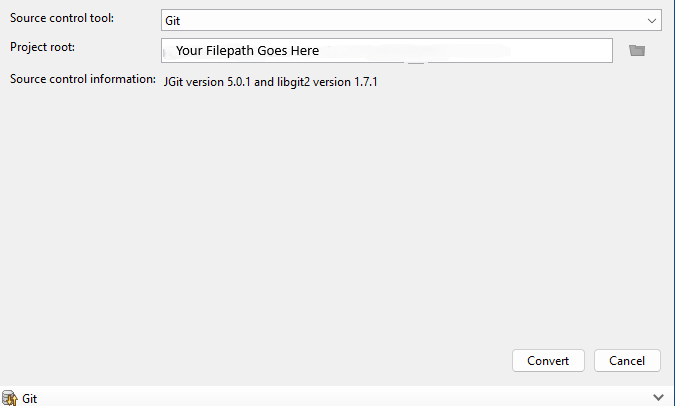

## Haciendo pull desde un repositorio remoto

Hacer pull desde un repositorio remoto actualiza el estado de tu repositorio local con cualquier cambio que se haya realizado en el remoto. Si eres la única persona trabajando en un proyecto, esto probablemente no suceda mucho, pero aún puedes hacer cambios, como ediciones al README, en la versión remota. Si trabajas con otras personas, esta es una excelente manera de compartir código y actualizaciones.

En un repositorio que has clonado, podrás hacer pull inmediatamente desde la sección Source Control

O dentro del panel de Source Control:

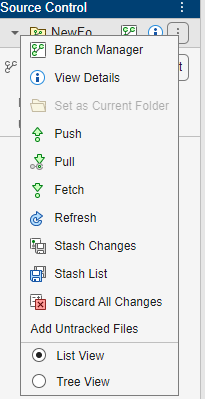

## Haciendo push a un repositorio remoto

Si tienes los permisos apropiados para agregar tu trabajo a un repositorio remoto, también puedes usar la sección Source Control de la cinta de herramientas del Proyecto para hacer **Push**, lo que actualizará el repositorio remoto con los commits locales que hayas realizado. Siempre es una buena práctica, incluso cuando trabajas solo, hacer **Pull** inmediatamente antes de hacer **Push**, solo para asegurarte de saber exactamente a qué estás agregando.

## Trabajando con colaboradores: branch y merge

Para mantener una copia limpia y común de un proyecto conjunto, los colaboradores individuales usualmente crean su propia rama para trabajar y, periódicamente, fusionan el trabajo que desean compartir de vuelta a la rama principal. Fusionar (merging) es el proceso de elegir qué partes del trabajo en conflicto, generado por diferentes contribuyentes, se combinarán para crear la copia guardada. Puedes encontrar instrucciones detalladas en la documentación sobre [ramas](https://www.mathworks.com/help/matlab/matlab_prog/create-manage-and-merge-git-branches.html) y [fusiones](https://www.mathworks.com/help/matlab/matlab_prog/resolve-git-conflicts-in-matlab.html).